## Task 5.2

%(a)
mu = 1;
tao = 1;
obs = 1 + randn(1,10);

% (b) (c) (d)
mu0 = 0;
lbd0 = 3;
a0 = 2;
b0 = 2;

%function defined at the end of the  script

% (e)
%run with initial values as priors
[s1,m1,a1,b1,F1,c1] = update_eqs(obs,length(obs),lbd0,a0,b0,mu0,mu0,(b0/(a0*lbd0)),a0,b0,1e-5)

s1 = 0.0674

m1 = 0.6887

a1 = 7.5000

b1 = 6.5744

F1 =    -8.6894
  -18.7448
  -14.7743
  -14.6921
  -14.6916
  -14.6916


c1 = 5


%runs with random values
[s2,m2,a2,b2,F2,c2] = update_eqs(obs,length(obs),lbd0,a0,b0,mu0,100*rand,100*rand,100*rand,100*rand,1e-5)

s2 = 0.0674

m2 = 0.6887

a2 = 7.5000

b2 = 6.5744

F2 =   -48.8994
  -82.5321
  -57.7212
  -38.9470
  -22.2925
  -15.2258
  -14.6974
  -14.6916
  -14.6916
  -14.6916


c2 = 9

[s3,m3,a3,b3,F3,c3] = update_eqs(obs,length(obs),lbd0,a0,b0,mu0,100*rand,100*rand,100*rand,100*rand,1e-5)

s3 = 0.0674

m3 = 0.6887

a3 = 7.5000

b3 = 6.5744

F3 =   -57.1632
  -71.4189
  -47.4441
  -29.2481
  -16.9696
  -14.7467
  -14.6919
  -14.6916
  -14.6916


c3 = 8

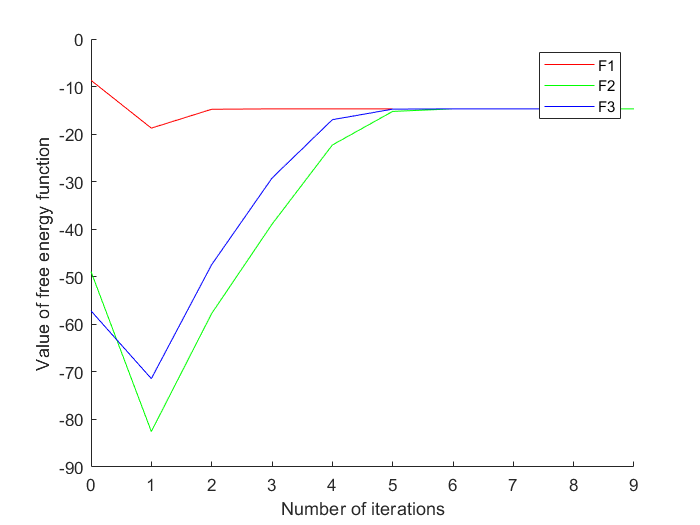

%plots for F
figure(1); hold on;
plot(linspace(0,c1,c1+1), F1, '-r');
plot(linspace(0,c2,c2+1), F2, '-g');
plot(linspace(0,c3,c3+1), F3, '-b');
xlabel('Number of iterations');
ylabel('Value of free energy function');
legend('F1', 'F2', 'F3');

function [s_2,m,a,b,F,c] = update_eqs(y,N,lbd0,a0,b0,mu0,m_i,s_i,a_i,b_i,threshold)
    c = 0;
    y_m = mean(y);
    F0 =-a_i*log(b_i) + gammaln(a_i) - gammaln(a0) + a0*log(b0) ...
    +0.5*log(lbd0) + log(sqrt(s_i)) -N/2*log(2*pi) +0.5;
    F = [F0];
    s_2 = 1/((a_i/b_i)*(N+lbd0));
    m = (lbd0*mu0+N*y_m)/(lbd0+N);
    a = a0 + (N+1)/2;
    b = b0 + 0.5*(sum((y-m_i).^2)+lbd0*(mu0-m_i)^2+(N+lbd0)*s_i);
    while 1
    c = c +1;
    F1 = -a*log(b) + gammaln(a) - gammaln(a0) + a0*log(b0) ...
    +0.5*log(lbd0) + log(sqrt(s_2)) -N/2*log(2*pi) +0.5;
    F = [F;F1];
    if (abs(F1-F0) <= threshold)
        break
    end
    F0 = F1;
    s_2 = 1/((a/b)*(N+lbd0));
    m = (lbd0*mu0+N*y_m)/(lbd0+N);
    a = a0 + (N+1)/2;
    b = b0 + 0.5*(sum((y-m).^2)+lbd0*(mu0-m)^2+(N+lbd0)*s_2);
   
    end

end



